clc
clear

%========= 交互式参数设置窗口 =========%
prompt = {
    '追踪粒子X坐标 (1-101):',...
    '追踪粒子Y坐标 (1-101):',...
    '激励源列号 (b):',...
    '总模拟时间 (tz):',...
    '时间步长 (dt):',...
    '稳定时间 (t0):'
};
defaults = {'52', '52', '3', '80', '0.02', '20'}; % 默认参数
dlgtitle = '参数设置';
dims = [1 50];
answer = inputdlg(prompt, dlgtitle, dims, defaults);

% 解析输入参数
track_particle = [str2double(answer{1}), str2double(answer{2})];
b = str2double(answer{3});
tz = str2double(answer{4});
dt = str2double(answer{5});
t0 = str2double(answer{6});

%========= 物理模型参数 (保持原样) =========%
k=3;
a=k;
f=0.5

f =      5.000000000000000e-01


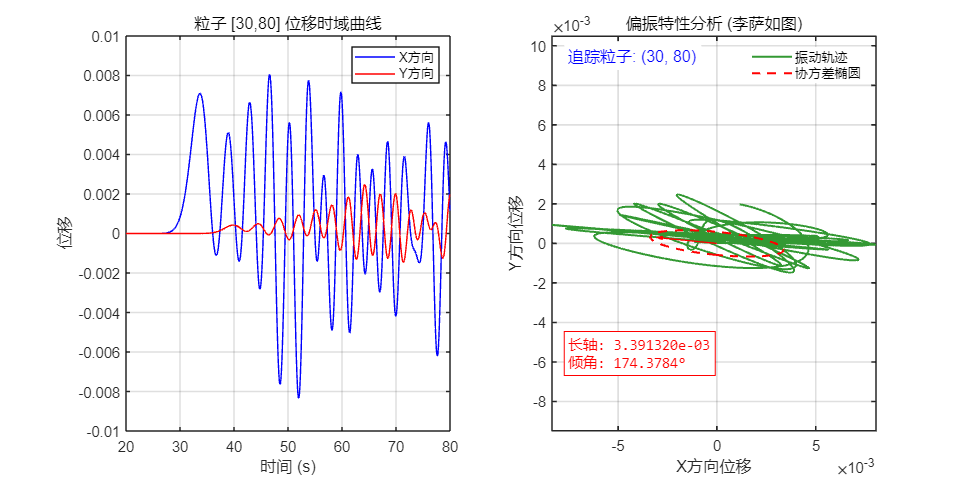

gama=500;
v=sqrt(2*k*exp(k)/(1+k)/gama);
A = v/(sqrt(2)*pi*f);
R = ones(101, 101);
M = ones(101, 101);

%========= 动态计算采样点数 =========%
j3 = round(tz/dt); % 自动计算采样点数

%========= 初始化数组 =========%
tl = zeros(j3,1);
x = zeros(101,101);
y = zeros(101,101);
vx = zeros(101,101);
vy = zeros(101,101);
xmn = zeros(j3,1);
ymn = zeros(j3,1);

%========= 晶格初始化 (保持原样) =========%
for i=1:101
    if mod(i,2)==0
        for j=2:2:100
            x(i,j) = 0.5*a*(j-51);
            y(i,j) = 0.5*sqrt(3)*a*(51-i);
        end
    else
        for j=1:2:101
            x(i,j) = 0.5*a*(j-51);
            y(i,j) = 0.5*sqrt(3)*a*(51-i);
        end
    end
end
xc = x; % 存储初始位置
yc = y;

%========= 动力学模拟 (保持原物理模型) =========%
for k1=1:j3
    t = (k1-1)*dt;
    tl(k1) = t;
    
    % 保存上一时刻状态
    xt = x; yt = y; vxt = vx; vyt = vy;
    
    % 施加激励
    for i=3:2:99
        xt(i,b) = A*sin(2*pi*f*t) + xc(i,b);
    end
    
    % 更新粒子状态
    for i=2:100
        if mod(i,2)==0
            cols = 4:2:98;
        else
            cols = 3:2:99;
        end
        for j = cols
            if j ~= b
                [x(i,j), y(i,j), vx(i,j), vy(i,j)] = xlg(xt(i,j),yt(i,j),vxt(i,j),vyt(i,j),dt,xt(i,j-2),xt(i+1,j-1),xt(i-1,j-1),xt(i-1,j+1),xt(i+1,j+1),xt(i,j+2),yt(i,j-2),yt(i+1,j-1),yt(i-1,j-1),yt(i-1,j+1),yt(i+1,j+1),yt(i,j+2),R(i,j),R(i,j-2),R(i+1,j-1),R(i-1,j-1),R(i-1,j+1),R(i+1,j+1),R(i,j+2),M(i,j),k); % 参数保持原样
            else
                x(i,b) = xt(i,b);
                y(i,b) = yt(i,b);
            end
        end
    end
    
    % 记录目标粒子位移
    xmn(k1) = x(track_particle(1), track_particle(2)) - xc(track_particle(1), track_particle(2));
    ymn(k1) = y(track_particle(1), track_particle(2)) - yc(track_particle(1), track_particle(2));
end

%========= 增强可视化 =========%
stable_idx = find(tl >= t0, 1);

fig = figure('Position', [200 200 1000 500], 'Color','w');

% 时域波形
subplot(1,2,1)
plot(tl(stable_idx:end), xmn(stable_idx:end), 'b',...
     tl(stable_idx:end), ymn(stable_idx:end), 'r')
title(sprintf('粒子 [%d,%d] 位移时域曲线',track_particle(1),track_particle(2)))
xlabel('时间 (s)'), ylabel('位移')
legend({'X方向','Y方向'},'Location','northeast')
grid on
set(gca, 'FontSize', 11, 'LineWidth', 1.2)

% 李萨如图
subplot(1,2,2)
plot(xmn(stable_idx:end), ymn(stable_idx:end), 'Color', [0.2 0.6 0.2], 'LineWidth', 1.5)
hold on

% 添加协方差椭圆
% 计算椭圆参数
cov_matrix = cov(xmn(stable_idx:end), ymn(stable_idx:end));
[V, D] = eig(cov_matrix);

% 提取长轴参数
[~, idx] = max(diag(D));            % 找到最大特征值索引
major_axis = sqrt(D(idx,idx));      % 长轴长度（标准差单位）
minor_axis = sqrt(D(3-idx,3-idx));  % 短轴长度

% 计算倾角（角度制）
if idx == 2
    angle_rad = atan2(V(2,2), V(1,2)); % 从最大特征值对应特征向量计算角度
else
    angle_rad = atan2(V(2,1), V(1,1));
end
angle_deg = rad2deg(angle_rad);

% 生成椭圆
theta = linspace(0, 2*pi, 100);
ellipse = (V*sqrt(D))*[cos(theta); sin(theta)];

% 绘制椭圆
plot(ellipse(1,:), ellipse(2,:), 'r--', 'LineWidth', 1.5)

% 绘制长轴方向线
hold on
quiver(0, 0, major_axis*cos(angle_rad), major_axis*sin(angle_rad),...
    'Color','r', 'LineWidth',1.0, 'MaxHeadSize',0.3)

% 添加参数标注（科学计数法显示）
text_str = {
    sprintf('长轴: %.6e', major_axis),...
    sprintf('倾角: %.4f°', angle_deg)  % 同时增加倾角精度
};
text(0.05, 0.15, text_str,...        % 调整到左下角
    'Units', 'normalized',...
    'FontSize', 11,...
    'FontName', 'Consolas',...       % 使用等宽字体对齐数字
    'Color', 'r',...
    'VerticalAlignment', 'bottom',...
    'BackgroundColor', [1 1 1 0.7],...
    'EdgeColor', 'r');


% 标注粒子坐标
text(0.05, 0.95, sprintf('追踪粒子: (%d, %d)', track_particle(1), track_particle(2)),...
    'Units', 'normalized', 'FontSize', 12, 'Color', 'b',...
    'BackgroundColor', [1 1 1 0.7])

% 图形美化
title('偏振特性分析 (李萨如图)')
xlabel('X方向位移'), ylabel('Y方向位移')
axis equal
grid on
set(gca, 'FontSize', 11, 'LineWidth', 1.2)
legend({'振动轨迹','协方差椭圆'}, 'Box', 'off')